# 关系运算

**Matlab**`中的关系运算符有下面六个：`

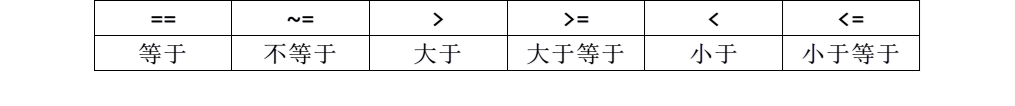

`关系运算符可以用来比较两个数组中元素的关系，如果结果为真，则`MATLAB`会返回逻辑值`1`；如果结果为假，则会返回逻辑值`0`。这里的逻辑值`1`和`0`实际上就是其他编程语言（例如`C`语言、`Java`等）中的布尔型`(bool)`变量，布尔型变量的值只有真（`true)`和假（`false`）。逻辑值`1`或`0`也可以简称为逻辑`1`或`0`，对应的英文为`logical 1`或`logical 0`。`

## `我们以等于命令``A==B``为例，举几个例子：`

**注意：一个等号是赋值，两****个连续的等号才是判断是否相等**

clc;clear

如果A和B都是标量（一个数），则直接进行判断。

A = 5;
B = 4;
% 一个等号是给变量赋值，两个等号才是判断是否相等的关系运算符
A == B  

ans = logical
   0

当一个为矩阵,另一个为标量的时候, 标量与矩阵中的每个元素进行关系运算。

A = randi(5) % 生成[1,5]上的一个随机整数

A = 4

B = randi(5,2,3)

B =      4     2     1
     4     4     4


A == B  

ans = 2×3 logical 数组
   1   0   0
   1   1   1


`在算术运算中，我们介绍了MATLAB中支持的兼容模式，关系运算中也支持。`

A = randi(5,1,3)

A =      1     2     1


B = randi(5,2,1)

B =      1
     5


A == B  

ans = 2×3 logical 数组
   1   0   1
   0   0   0


注意：NaN(`不定值或缺失值`)相互之间不相等

A = NaN;
B = NaN;
A == B

ans = logical
   0

A=inf;
B=inf;
A==B

ans = logical
   1

易错点：连续使用关系运算符

0 == 0 == 0   % 返回 logical 0 (false)

ans = logical
   0

1 == 1 == 1   % 返回 logical 1 (true)

ans = logical
   1

-1 < 0 < 1   % 返回 logical 0 (false)

ans = logical
   0

1 > 0 > -1   % 返回 logical 1 (true)

ans = logical
   1

`逻辑值1和逻辑值0不仅仅用于表示真true和假false，它们在进行计算时也可以被视为数值1和数值0`

x = randi(10, 3, 4)

x =      7     4     8     1
     8     7     1     1
     8     2     3     9


y = x > 5

y = 3×4 logical 数组
   1   0   1   0
   1   1   0   0
   1   0   0   1


% 也可以写成y = (x>5)，加括号会让运算的顺序更清晰
sum(y)  % 计算每一列的和，表示x的每一列中大于5的元素个数

ans =      3     1     1     1


sum(y(:))  % 计算所有元素的和，表示x中大于5的元素个数

ans = 6

`模拟投硬币`10`万次，计算出现正面的次数和频率`

n = 1e5;                % 科学计数法表示100000
x = randi([0,1], n, 1); % 0表示正面，1表示反面
s = sum(x == 0)         % 出现正面的次数

s = 49970

pl = s / n              % 频率

pl = 0.4997

## `判断浮点数是否相等`

C = 0.5-0.4-0.1

C = -2.7756e-17

C == 0    

ans = logical
   0


C

C = -2.7756e-17

**解决方法：使用容差 tol（而不是使用 ==）比较浮点数。**

`例如：要比较`A`和`B`两个数是否相等，只需要满足：`|A − B| `≤` tol `，这里的`tol`是一个非常非常小的正数，`

`例如`tol`可以取成`1e-12(10`的`-12`次方`)`。`tol`越小，要求越严格。`

abs(C-0) <= 1e-12

ans = logical
   1


C = 0.5 - 0.1 - 0.4

C = 0

C == 0

ans = logical
   1


配套的讲解视频可在b站免费观看：

《MATLAB教程新手入门篇（数学建模清风主讲，适合零基础同学观看）》

[https://www.bilibili.com/video/BV1dN4y1Q7Kt/](https://www.bilibili.com/video/BV1dN4y1Q7Kt/)